Kp = 1.6;
Ki = 0.8;
Kd = 0.8;
Kc = 1.8;

[a,b,c,d]=linmod('model1_analysis');
sys = ss(a,b,c,d)

sys =
 
  A = 
        x1   x2   x3   x4
   x1    0    0    1   50
   x2    0    0   -1    0
   x3    1    0    0    0
   x4    0    0    0  -10
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
         x1    x2    x3    x4
   y1  -0.8   0.8  -1.6     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



damp(sys)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  1.00e+00    -1.00e+00       1.00e+00        -1.00e+00    
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    
 -1.00e+01     1.00e+00       1.00e+01         1.00e-01    


w = (2*pi)/(12.79-6.3)

w = 0.9681

[a,b,c,d]=linmod('model1_analysis_descf')

a =      0     0     1    50
     0     0    -1     0
     1     0     0     0
     0     0     0   -10


b =      0
     0
     0
     1


c =    -0.8000    0.8000   -1.6000         0


d = 0

sys = -ss(a,b,c,d)

sys =
 
  A = 
        x1   x2   x3   x4
   x1    0    0    1   50
   x2    0    0   -1    0
   x3    1    0    0    0
   x4    0    0    0  -10
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
         x1    x2    x3    x4
   y1   0.8  -0.8   1.6     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



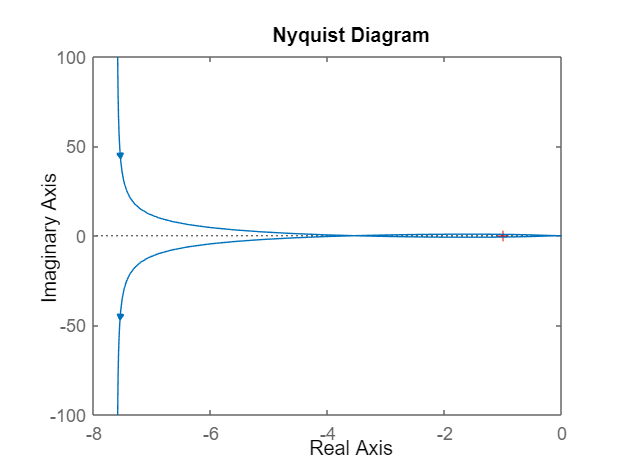

nyquist(sys)

w = 1.12

w = 1.1200

N = 1/3.55

N = 0.2817

x0 = (4*1)/(pi*N)

x0 = 4.5200

R=abs(freqresp(sys,3*w)/freqresp(sys,w))

R = 0.3179

% Kaw= 0.1
% [a,b,c,d]=linmod('model1_analysis_descf_aw')
% sys = -ss(a,b,c,d)
% nyquist(sys)
% 
% Kaw= 0.3
% [a,b,c,d]=linmod('model1_analysis_descf_aw')
% sys = -ss(a,b,c,d)
% nyquist(sys)
% 
% Kaw= 0.5
% [a,b,c,d]=linmod('model1_analysis_descf_aw')
% sys = -ss(a,b,c,d)
% nyquist(sys)

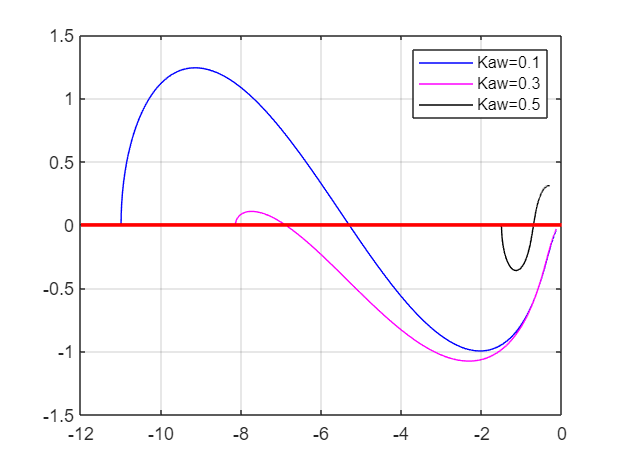

figure(7); clf;
omeg=[0:0.01:15];
icoul=0; coul='bmk';
for Kaw=[0.5 0.7 10]
    icoul=icoul+1;
    [a,b,c,d]=linmod('model1_analysis_descf_aw');
    sys=-ss(a,b,c,d);
    [re,im]=nyquist(sys,omeg);
    re=squeeze(re); im=squeeze(im);
    plot(re,im,coul(icoul)); hold on;
end
plot([-12 0],[0 0],'r','LineWidth',2);
legend('Kaw=0.1','Kaw=0.3','Kaw=0.5','Location','NorthEast');
grid